# OptForce Tutorial

## Sebastián N. Mendoza F.  May 30th, 2017. snmendo@uc.cl

In this tutorial we will run optForce. For a detailed description of the procedure, please see[1]: Ranganathan S, Suthers PF, Maranas CD (2010) OptForce: An Optimization Procedure for Identifying All Genetic Manipulations Leading to Targeted Overproductions. PLOS Computational Biology 6(4): e1000744. https://doi.org/10.1371/journal.pcbi.1000744. 

Briefly, the problem is to find a set of interventions of size "K" such that when these interventions are applied to a wild-type strain, the mutant created will produce a particular target of interest in a higher rate than the wild-type strain. The interventions could be knockouts (lead to zero the flux for a particular reaction), upregulations(increase the flux for a particular reaction) and downregulations (decrease the flux for a particular reaction). 

This prodecure consists on three steps:

1) Perform FVA in both wild type and mutant strains

2) Find the must sets, i.e, reactions that MUST increase or decrease their flux in order to achieve the phenotype in the mutant strain. 

## Figure 1.

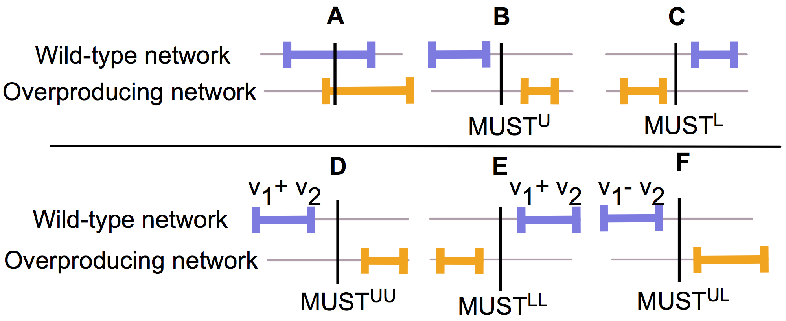

3) Find the interventions needed that will ensure a increased production of the target of interest

For example, imagine that we would like to increase the production of succinate in Escherichia coli. Which are the interventions needed to increase the production of succinate? We will approach this problem in this tutorial and we will see how each of the three steps are solved. 

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\Genoma-01\Documents\fork-cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solv

In this tutorial we will run steps 2 and 3 in GAMS and we will use MATLAB to call GAMS. Therefore, GAMS must be intalled in the system before running this turorial. After GAMS installation, we have to add tha path where GAMS in located

gamsPath = 'C:\GAMS\win64\24.8';
added = addGAMSPath(gamsPath);

GAMS path was added to MATLABPATH


Now that we have added GAMS path we can start with the modelling

## Modelling

First we load the model. This model comprises only 90 reactions, which describe the central metabolism of E. coli [2].

Then, we change the objective function to maximize biomass ("R75"). We also change the lower bounds, so E. coli will be able to consume glucose, oxygen, sulfate, ammomium, citrate and glycerol. Finally, we change the reversibility flag because these reactions are now reversible

model = []; load('AntCore');
model.c(strcmp(model.rxns,'R75')) = 1;
model = changeRxnBounds(model, 'EX_gluc', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_gluc')) = 1;
model = changeRxnBounds(model, 'EX_o2', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_o2')) = 1;
model = changeRxnBounds(model, 'EX_so4', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_so4')) = 1;
model = changeRxnBounds(model, 'EX_nh3', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_nh3')) = 1;
model = changeRxnBounds(model, 'EX_cit', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_cit')) = 1;
model = changeRxnBounds(model, 'EX_glyc', -100, 'l'); model.rev(strcmp(model.rxns, 'EX_glyc')) = 1;

pathTutorial = which('optForceTutorialGAMS.m');
pathstr = fileparts(pathTutorial);
cd(pathstr)


We define an ID for this run. Each time you run the functions associated to the optForce procedure, some folders will be generated to store inputs and ouputs. These folder will be located in the folder defined in your run ID. Thus if your runID is ''TestOptForce", the structure of the folder will be the following:

`├── CurrentFolder`

`|   ├── TestOptForce`

`|   |   ├── Inputs`

`|   |   └── Outputs`

To avoid the generation of inputs and outputs folders, set keepInputs = 0, printExcel = 0, printText = 0 and keepGamsOutputs = 0

Also, a report of the run is generated each time you run the functions associated to the optForce procedure. So, the idea is to give a different runID each time you run the functions, so you will be able to see the report (inputs used, outputs generated, errors in the run) for each run.

We define then our runID

runID = 'TestOptForce';

## Step 1: Flux Variability Analysis

We run the first step which consist on performing a FVA for both wild-type and mutant strains 

We define constraints for each strain

Constr_WT = struct('rxnList', {{'R75'}}, 'rxnValues', 14, 'rxnBoundType', 'b');
Constr_MT = struct('rxnList', {{'R75','EX_suc'}}, 'rxnValues', [0, 155.55], 'rxnBoundType', 'bb');

We  run the FVA analysis for both strains

[minFluxes_WT, maxFluxes_WT, minFluxes_MT, maxFluxes_MT,~,~] = FVAOptForce(model, Constr_WT, Constr_MT);
disp([minFluxes_WT, maxFluxes_WT, minFluxes_MT, maxFluxes_MT]);

  -90.1251   97.1300   44.4313  100.0000
         0   86.0700   44.4375  100.0000
         0   86.0700   44.4375  100.0000
  -56.1567   86.0700  -44.4500   11.1143
   21.3033  163.5300   55.5500  111.1143
   -3.0777  154.8640   55.5500  111.1143
         0  151.5086         0   55.5625
         0  187.2551         0   55.5687
         0  169.5163         0    0.0187
  -10.0660  102.9449    0.0000    0.0125
   10.0660   66.5714   -0.0000    0.0062
  -10.0660  102.9449    0.0000    0.0125
  -48.9454    7.5600   -0.0062    0.0000
  -53.9994    2.5060   -0.0062    0.0000
  -53.9994    2.5060   -0.0062    0.0000
   -2.5060   53.9994   -0.0000    0.0062
         0   86.0700         0   55.5625
   -0.0000   86.0700         0   55.5625
    9.7020  114.6466   55.5500   55.5625
         0   56.5564   55.5500   55.5571
   16.0264  145.2048  155.5500  155.5563
   16.0264  145.2048  155.5500  155.5563
    0.9344  130.1128  155.5500  155.5563
   -5.6736  123.5048  155.5500  155.5563
         0  118.

Now, the run the second step of OptFoce.

## Step 2: Find Must Sets

Fow now, only functions to find first and second order must sets are supported. As depicted in Fig. 1, the first order must sets are MUSTU and MUSTL; and second order must sets are MUSTUU, MUSTLL and MUSTUL

**A) Finding first order must sets**

We define constraints

constrOpt = struct('rxnList', {{'EX_gluc','R75','EX_suc'}}, 'values', [-100, 0, 155.5]', 'sense', 'EEE');

We then run the functions findMustLWithGAMS.m and findMustUWithGAMS.m that will find mustU and mustL sets, respectively.

Important: To run these function you will need a solver able to solve Mixed Integer Linear Programming (MILP or MIP) problems. Some popular options are: cplex and gurobi. You can see which gams solvers are available in your systems to solve MIP problems by running checkGAMSSolvers('MIP')

solvers = checkGAMSSolvers('MIP'); disp(solvers);

  Columns 1 through 17

    'AMPL'    'BARON'    'BDMLP'    'BENCH'    'CBC'    'CONVERT'    'CPLEX'    'EXAMINER'    'GAMSCHK'    'GUROBI'    'KESTREL'    'LINDO'    'LINDOGLOBAL'    'LINGO'    'LOCALSOLVER'    'MOSEK'    'MPECDUMP'

  Columns 18 through 25

    'OsiCplex'    'OsiGurobi'    'OsiMosek'    'OsiXpress'    'PYOMO'    'SCIP'    'XA'    'XPRESS'



We run then findMustLWithGAMS.m and findMustUWithGAMS.m. 

Here, the following inputs are provided (they are showed by order):

model, minFluxesW, maxFluxesW, constrOpt were defined before. 

solverName = 'cplex'

runID = ''TestOptForce' // outputFolder = '' // outputFileName = '' 

printExcel = 1 // printText = 1 // printReport = 1 // keepInputs = 1 // keepGamsOutputs = 1 // verbose = 0

**i) MustL Set: **

[mustLSet, pos_mustL] = findMustLWithGAMS(model, minFluxes_WT, maxFluxes_WT, constrOpt, 'cplex', runID, '', '', 1, 1, 1, 1, 1, 0);

We display the reactions that belongs to the mustL set

disp(mustLSet)

    'R11'
    'R26'
    'R37'
    'R38'
    'R39'
    'R40'
    'R41'
    'R42'
    'R43'
    'R46'
    'R48'
    'R49'
    'R50'
    'R51'
    'R52'
    'R53'
    'R54'
    'R55'
    'R56'
    'R57'
    'R58'
    'R59'
    'R60'
    'R61'
    'R73'
    'R74'
    'PSEUDOpyr_1'
    'PSEUDOpep_1'
    'PSEUDOco2_1'



**ii) MustU set: **

[mustUSet, pos_mustU] = findMustUWithGAMS(model, minFluxes_WT, maxFluxes_WT, constrOpt, 'cplex', runID, '', '', 1, 1, 1, 1, 1, 0);

We display the reactions that belongs to the mustU set

disp(mustUSet)

    'R21'
    'R22'
    'R23'
    'R24'
    'R33'
    'R34'
    'R35'
    'R36'
    'R69'
    'EX_pdo'
    'EX_nh3'
    'EX_so4'
    'SUCt'



**B) Finding second order must sets **

First, we define the reactions that will be exluded from the analysis. It it suggested to eliminate reactions found in the previous step as well as exchange reactions

constrOpt = struct('rxnList', {{'EX_gluc','R75','EX_suc'}}, 'values', [-100, 0, 155.5]', 'sense', 'EEE');
exchangeRxns = model.rxns(cellfun(@isempty, strfind(model.rxns, 'EX_')) == 0);
excludedRxns = unique([mustUSet; mustLSet; exchangeRxns]);
mustSetFirstOrder = unique([mustUSet; mustLSet]);

Now, we run the functions for finding second order must sets

**i) MustUU: **

[mustUU, pos_mustUU, mustUU_linear, pos_mustUU_linear] = findMustUUWithGAMS(model,...
    minFluxes_WT, maxFluxes_WT, constrOpt, excludedRxns, mustSetFirstOrder, 'cplex',...
    runID, '', '', 1, 1, 1, 1, 1, 0);

We display the reactions that belongs to the mustUU set

disp(mustUU);

    'R30'    'R65'
    'R65'    'R31'



**ii) MustLL: **

[mustLL, pos_mustLL, mustLL_linear, pos_mustLL_linear] = findMustLLWithGAMS(model,...
    minFluxes_WT, maxFluxes_WT, constrOpt, excludedRxns, mustSetFirstOrder, 'cplex',...
    runID, '', '', 1, 1, 1, 1, 1, 0);

We display the reactions that belongs to the mustLL set. In this case, MustLL is an empty array because no reaction was found in the mustLL set.

disp(mustLL);

**iii) MustUL: **

[mustUL, pos_mustUL, mustUL_linear, pos_mustUL_linear] = findMustULWithGAMS(model,...
    minFluxes_WT, maxFluxes_WT, constrOpt, excludedRxns, mustSetFirstOrder, 'cplex',...
    runID, '', '', 1, 1, 1, 1, 1, 0);

We display the reactions that belongs to the mustUL set. In this case, MustUL is an empty array because no reaction was found in the mustUL set.

disp(mustUL);

## Step 3: OptForce

We define constraints and we define "K" the number of interventions allowed, "n_sets" the maximum number of sets to find, and "targetRxn" the reaction producing the metabolite of interest (in this case, succinate). 

Additionally, we define the mustU set as the union of the reactions that must be upregulated in both first order and second order must sets; and mustL set as the union of the reactions that must be downregulated in both first order and second order must sets 

mustU = unique(union(mustUSet, mustUU));
mustL = unique(union(mustLSet, mustLL));
targetRxn = 'EX_suc';
k = 1;
n_sets = 1;
constrOpt = struct('rxnList', {{'EX_gluc','R75'}}, 'values', [-100, 0], 'sense', 'EE');
excludedRxns = {};

[optForceSets, posOptForceSets, typeRegOptForceSets] = optForceWithGAMS(model, targetRxn, mustU, mustL, minFluxes_WT, maxFluxes_WT, minFluxes_MT, maxFluxes_MT,k,n_sets,constrOpt,excludedRxns,runID,'','','cplex',1,1,1,1,1,0);

We display the reactions found by optForce

disp(optForceSets)

    'SUCt'



The reaction found was "SUCt", i.e. a transporter for succinate (a very intuitive solution).

Next, we will increase "k" and we will exclude "SUCt" from upregulations to found non-intuitive solutions. We will only search for the 5 best solutions, but you can try with a higher number.

We will change the runID to save both resutls (k = 1 and K = 2) in diffetent folders

k = 2;
n_sets = 5;
runID = 'TestOptForce2';
excludedRxns = struct('rxnList', {{'SUCt'}}, 'typeReg','U');
[optForceSets, posOptForceSets, typeRegOptForceSets] = optForceWithGAMS(model, targetRxn, mustU, mustL, minFluxes_WT, maxFluxes_WT, minFluxes_MT, maxFluxes_MT,k,n_sets,constrOpt,excludedRxns,runID,'','','cplex',1,1,1,1,1,0);

We display the reactions found by optForce

disp(optForceSets)

    'R23'    'R25'
    'R24'    'R26'
    'R24'    'R26'
    'R24'    'R63'
    'R23'    'R63'



## References

[1] Ranganathan S, Suthers PF, Maranas CD (2010) OptForce: An Optimization Procedure for Identifying All Genetic Manipulations Leading to Targeted Overproductions. PLOS Computational Biology 6(4): e1000744. https://doi.org/10.1371/journal.pcbi.1000744.

[2] Maciek R. Antoniewicz, David F. Kraynie, Lisa A. Laffend, Joanna González-Lergier, Joanne K. Kelleher, Gregory Stephanopoulos, Metabolic flux analysis in a nonstationary system: Fed-batch fermentation of a high yielding strain of E. coli producing 1,3-propanediol, Metabolic Engineering, Volume 9, Issue 3, May 2007, Pages 277-292, ISSN 1096-7176, https://doi.org/10.1016/j.ymben.2007.01.003.